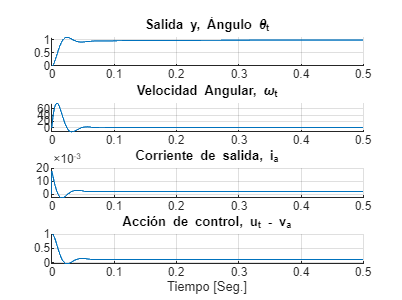

clear; clc;  % Limpia variables y consola

X = -[0; 0; 0; 0];  % Estado inicial del motor: velocidad, aceleración, corriente y posición
t_etapa = 1e-7;     % Paso de simulación. Muy pequeño para lograr alta precisión
titaRef = 1;        % Referencia del ángulo deseado del eje del motor
tF = 0.5;           % Tiempo total de simulación (0.5 segundos)
u = 0;              % Inicialización de la acción de control (voltaje aplicado)
u_max = 12;         % Límite superior de tensión (saturación realista del actuador)
u_min =-12;        % Límite inferior de tensión

% Constantes del controlador PID
% Se comentaron valores iniciales y se usaron valores óptimos en su lugar
% Kp = 0.1;
% Ki = 0.01;
% Kd = 5;

% Valores óptimos seleccionados para mejorar el rendimiento
Kp = 1;     % Ganancia proporcional: respuesta rápida al error
Ki = 8;     % Ganancia integral: elimina el error en estado estacionario
Kd = 0;     % Ganancia derivativa: no se usa aquí

color = '';   % Color de línea en las gráficas (puede usarse para comparativas)

% Tiempo de muestreo (coincide con t_etapa)
Ts = t_etapa;

% Cálculo de coeficientes para la implementación discreta del PID (en forma recursiva)
A1 = ((2*Kp*Ts)+(Ki*(Ts^2))+(2*Kd))/(2*Ts);
B1 = (-2*Kp*Ts+Ki*(Ts^2)-4*Kd)/(2*Ts);
C1 = Kd/Ts;

ii=0;  % Contador de pasos de simulación
e = zeros(round(tF/t_etapa),1);  % Vector para almacenar el error en cada paso

% Bucle de simulación
for t=0:t_etapa:tF
ii = ii+1;
k = ii+2;  % índice para almacenar errores con desfase (evitar problemas en los primeros pasos)


% Simulación del modelo del motor con la acción de control actual
X = modmotor2(t_etapa, X, u);

% Cálculo del error: diferencia entre la referencia y el ángulo actual (X(4) = tita)
e(k) = titaRef - X(4);

% Cálculo de la nueva acción de control PID (forma recursiva discreta)
u = u + A1*e(k) + B1*e(k-1) + C1*e(k-2);

% Saturación de la acción de control (se limita a ±12V)
if u > u_max
    u = u_max;
end
if u < u_min
    u = u_min;
end

% Almacenamiento de variables del sistema
x1(ii) = X(1);  % Velocidad angular (omega)
x2(ii) = X(2);  % Derivada de la velocidad angular (wp)
x3(ii) = X(3);  % Corriente de armadura (ia)
x4(ii) = X(4);  % Posición angular (tita)
acc(ii) = u;    % Acción de control (voltaje aplicado)

end

% Vector de tiempo para graficar
t = 0:t_etapa:tF;

% Gráficos de las variables
subplot(4,1,1); hold on; grid on;
plot(t,x4,color); title('Salida y, Ángulo \theta_t');

subplot(4,1,2); hold on; grid on;
plot(t,x1,''); title('Velocidad Angular, \omega_t');

subplot(4,1,3); hold on; grid on;
plot(t,x3,''); title('Corriente de salida, i_a');

subplot(4,1,4); hold on; grid on;
plot(t,acc,''); title('Acción de control, u_t - v_a');
xlabel('Tiempo [Seg.]');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNCION QUE MODELA EL MOTOR                        %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [X] = modmotor2(t_etapa, xant, accion)
% Constantes del motor (obtenidas del modelo físico real)
Laa = 366e-6;   % Inductancia de armadura
J = 5e-9;       % Inercia del rotor
Ra = 55.6;      % Resistencia de armadura
B = 0;          % Coeficiente de fricción (se considera despreciable)
Ki = 6.49e-3;   % Constante del motor (par generado por corriente)
Km = 6.53e-3;   % Constante de f.e.m. (tensión inducida por velocidad)
Va = accion;    % Voltaje de armadura (control)
h = 1e-7;       % Paso de integración interna
TL = 2.128e-7;  % Par de carga externa (resistencia al movimiento)

% Estados anteriores del motor
omega = xant(1);  % Velocidad angular
wp = xant(2);     % Derivada de la velocidad (aceleración)
ia = xant(3);     % Corriente de armadura
tita = xant(4);   % Posición angular

% Bucle de integración de las ecuaciones diferenciales
for ii = 1:t_etapa/h
    % Ecuaciones del modelo dinámico del motor (forma diferencial)
    wpp = (-wp*(Ra*J + Laa*B) - omega*(Ra*B + Ki*Km) + Va*Ki)/(J*Laa);  % Derivada de la aceleración
    iap = (-Ra*ia - Km*omega + Va)/Laa;                                % Derivada de la corriente

    % Integración numérica usando Euler explícito
    wp = wp + h * wpp;          % Actualización de aceleración
    wp = wp - ((1/J) * TL);     % Influencia del par de carga
    ia = ia + h * iap;          % Actualización de corriente
    omega = omega + h * wp;     % Integración de la velocidad
    tita = tita + h * omega;    % Integración de la posición
end

% Salida de nuevos estados
X = [omega, wp, ia, tita];

end